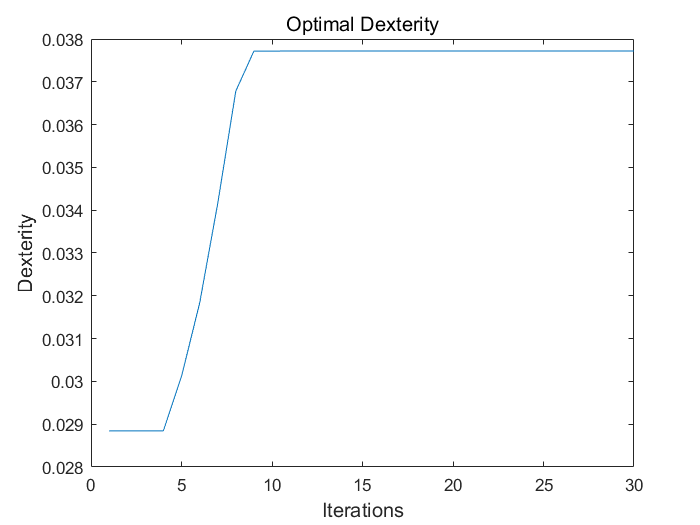

% 清空运行环境 。
clc
clear
% 随机初始果蝇群体位置 。
X_axis=10*rand();
Y_axis=10*rand();
%设置参数
maxgen=30; %迭代次数
sizepop=100; %种群规模
% 给定系数：
a1 =    0.008256;
b1 =      0.3261;
c1 =      0.2283;
a2 =    0.001483;
b2 =      0.6017;
c2 =      0.1243;
a3 =     0.03041;
b3 =      0.4862;
c3 =      0.7649;


%果蝇寻优开始
for i=1:sizepop
%附与果蝇个体利用嗅觉搜寻食物之随机方向与距离
X(i)=X_axis+2*rand()-1;
Y(i)=Y_axis+2*rand()-1;
%由于无法得知食物位置，因此先估计与原点之距离D，再计算味道浓度判定值(S)，此值为距离之倒数
D(i)=((X(i)-1)^2+Y(i)^2)^0.5;
S(i)=1/D(i);
% 味道浓度判定值 (S) 代入味道浓度判定函数( ( 或称为  Fitness function)以求出 该果蝇个体位置的味道浓度 (Smelli) 。
%Smell(i)=p1*S(i)^5+p2*S(i)^4+p3*S(i)^3+p4*S(i)^2+p5*S(i)+p6;
Smell(i) = a1*exp(-((S(i)-b1)/c1)^2) + a2*exp(-((S(i)-b2)/c2)^2) +  a3*exp(-((S(i)-b3)/c3)^2);

end
%找出此果蝇群体的中味道浓度最高的果蝇(求极大值)
[bestSmell bestindex]=max(Smell);
%保留最佳味道浓度值与 x x 、y y  坐标 ， 此时果蝇群体利用视觉往该位置飞去 。
X_axis=X(bestindex);
Y_axis=Y(bestindex);
Smellbest=bestSmell;


%果蝇迭代寻优开始
for g=1:maxgen
%附与果蝇个体利用嗅觉搜寻食物之随机方向与距离
for i=1:sizepop
X(i)=X_axis+2*rand()-1;
Y(i)=Y_axis+2*rand()-1;
%*** 由于无法得知食物位置, 因此先估计与原点之距离 (Dist),再计算味道浓度判定值 (S),此值为距离之倒数
D(i)=(X(i)^2+Y(i)^2)^0.5;
S(i)=1/D(i);

%判定值 (S) 代入判定函数以求出该果蝇位置的味道浓度 (Smelli) 。
Smell(i) = a1*exp(-((S(i)-b1)/c1)^2) + a2*exp(-((S(i)-b2)/c2)^2) +  a3*exp(-((S(i)-b3)/c3)^2);
end
%找出此果蝇群体的中味道浓度最高的果蝇( 求极大值)
[bestSmell bestindex]=max(Smell);
%判断味道浓度是否优于前一迭代味道浓度, 若是则保留最佳味道浓度值与 x x 、y y  坐标 ， 此时果蝇群体利用视觉往该位置飞去 。
if bestSmell>Smellbest
X_axis=X(bestindex);
Y_axis=Y(bestindex);
Smellbest=bestSmell;
end
%每代最优 smell值纪录到数组中,并记录最优迭代坐标
yy(g)=Smellbest;
Xbest(g)=X_axis;
Ybest(g)=Y_axis;
end

index_x = 1./sqrt(Xbest.^2+Ybest.^2);
figure(1)
plot(yy)
title('Optimal Dexterity','fontsize',12)
xlabel('Iterations','fontsize',12);
ylabel('Dexterity','fontsize',12);

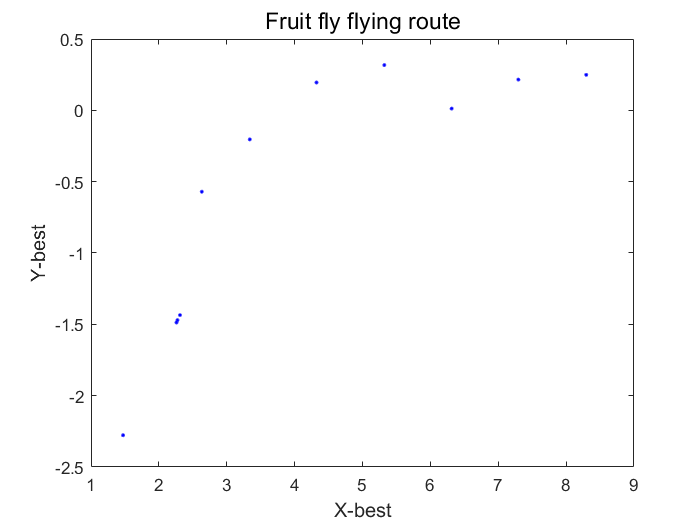

figure(2)
plot(Xbest,Ybest,'b.');
title('Fruit fly flying route','fontsize',14)
xlabel('X-best','fontsize',12);
ylabel('Y-best','fontsize',12);

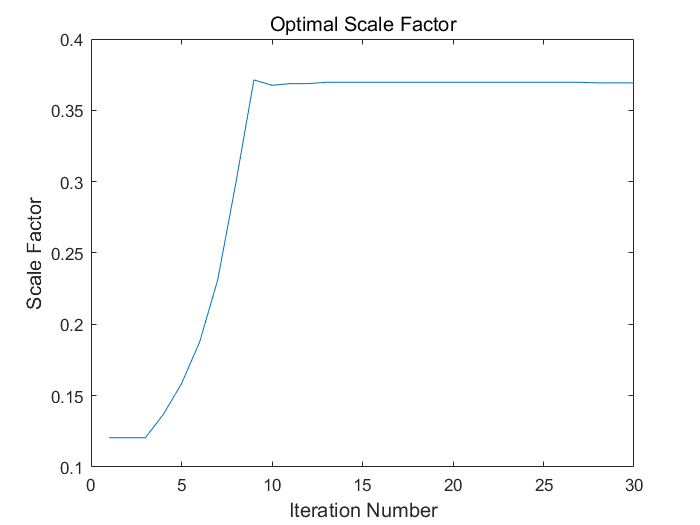

figure(3)
plot(index_x);
title('Optimal Scale Factor','fontsize',12)
xlabel('Iteration Number','fontsize',12);
ylabel('Scale Factor','fontsize',12);